% modulation
Am = .3; fm = 4000;    % Vpp

% Carrier components
Ac = 2; fc = 45000;
syms t

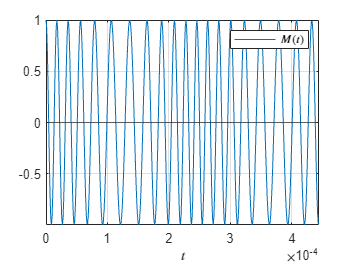

kf = 10;
% modulated signal
s = Ac*cos(2*pi*fc*t + kf*Am*sin(2*pi*fm*t))/2;
% time vector
t0 = 0:1/(20*fc):20/fc;

% plot
plot(t0, subs(s, t0))
yline(0)
grid on
axis tight
xlabel $t$ Interpreter latex
legend $M(t)$ Interpreter latex


% demodulation
d = diff(s, 't');

o=matlabFunction(d);

h = abs(hilbert(o(t0)))

h = 1.0e+05 *

    1.3440    2.2058    2.8486    3.3379    3.7017    3.9564    4.0936    4.1541    4.1157    4.0298    3.8818    3.7184    3.5444    3.3892    3.2750    3.2037    3.1967    3.2280    3.3031    3.3901    3.4809    3.5595    3.6116    3.6406    3.6320    3.6016    3.5405    3.4676    3.3831    3.3006    3.2295    3.1721    3.1411    3.1270    3.1383    3.1599    3.1928    3.2256    3.2529    3.2721    3.2745    3.2661    3.2381    3.2013    3.1503    3.0954    3.0367    2.9800    2.9306    2.8876


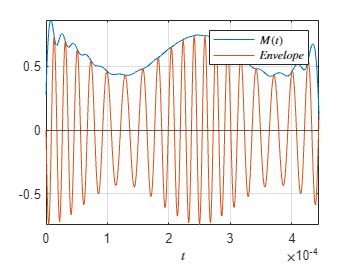


plot(t0, [h; subs(d, t0)]/4.8137e5)
yline(0)
grid on
axis tight
xlabel $t$ Interpreter latex
legend $M(t)$ $Envelope$ Interpreter latex